**LEP 4-5: Calculating the Equilibrium Conversion**

xguess = [0.5 0.4]; % initial guess vector for Xef and Xeb

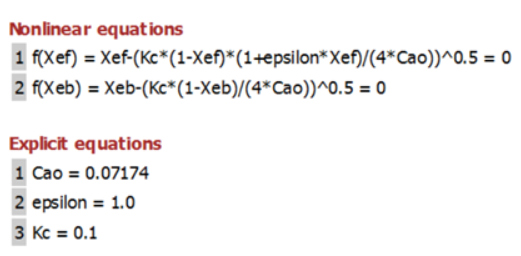

sol=fsolve(@MNLEfun,xguess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Xeb=sol(1,2);
Xef=sol(1,1);
disp('The equilibrium conversion in a constant-volume batch reactor is')

The equilibrium conversion in a constant-volume batch reactor is


Xeb

Xeb = 0.4413

disp('The equilibrium conversion in a flow reactor is')

The equilibrium conversion in a flow reactor is


Xef

Xef = 0.5084

function fx = MNLEfun(x)
Xef = x(1); 
Xeb = x(2);
% Explicit equations
yAo=1;
Cto=0.07174; 
Cao = yAo*Cto;
epsilon = yAo*1; 
Kc = 0.1; 
% Nonlinear equations
fx(1,1) = Xef - ((Kc * (1 - Xef) * (1 + epsilon * Xef) / (4 * Cao)) ^ 0.5); 
fx(2,1) = Xeb - ((Kc * (1 - Xeb) / (4 * Cao)) ^ 0.5); 
end